### Lookup table (LUT) generator for sinusoidal PWM generation in C/C++

Function takes in inputs for:

- The number of datapoints (not zero indexed)

- Period in radians

- Peak to peak wave height

- Positive offset for most timer systems ('y' or 'n' to enable/disable)

- Wave type of Sine or Cosine ('s' or 'c')

- Format for output ('h' or 'd' for Hex or Decimal respectively)

The final output can be directly copy pasted into a C/C++ microprocessor IDE for use SPWM generation or for other functions that require a fast sine lookup.

function sinCosTable = generateSinCosTable(nData, period, peakToPeak, posOffset, wave, format)
stepSize = period/nData; % determine wave generation step size
sinCosTable.rawValues = zeros(1,nData); % initialize empty array for raw values
if wave == 's' % Sine wave generator
    fprintf('Sine wave selected \n')
    sinCosTable.formatted = sprintf('// Auto generated sine LUT from SinCosLUTGenerator.m, credit: Alec Marshall \r\n');
    if peakToPeak <= 255 && posOffset == 'y'
        sinCosTable.formatted = append(sinCosTable.formatted, sprintf('uint8_t sinTable[%d] = {\r\n', nData));
    elseif peakToPeak <= 127 && posOffset == 'n'
        sinCosTable.formatted = append(sinCosTable.formatted, sprintf('int8_t sinTable[%d] = {\r\n', nData));
    elseif peakToPeak > 255 && posOffset == 'y'
        sinCosTable.formatted = append(sinCosTable.formatted, sprintf('uint16_t sinTable[%d] = {\r\n', nData));
    elseif peakToPeak > 127 && posOffset == 'n'
        sinCosTable.formatted = append(sinCosTable.formatted, sprintf('int16_t sinTable[%d] = {\r\n', nData));
    end
    for i = 1:nData
        if posOffset == 'y'
            sinCosTable.rawValues(1,i) = round((sin(stepSize*(i-1))+1)*peakToPeak/2,0);
        elseif posOffset == 'n'
            sinCosTable.rawValues(1,i) = round(sin(stepSize*(i-1))*peakToPeak/2,0);
        else
            fprintf('Not a valid offset selection \n')
            sinCosTable.rawValues = [];
            sinCosTable.formatted = 'Not a valid offset selection';
            return
        end
        if mod(i,8) == 0
            sinCosTable.formatted = append(sinCosTable.formatted, newline);
        end
        if format == 'd'
            sinCosTable.formatted = append(sinCosTable.formatted, sprintf('%d,',sinCosTable.rawValues(i)));
        elseif format == 'h'
            sinCosTable.formatted = append(sinCosTable.formatted, sprintf('0x%X,',sinCosTable.rawValues(i)));
        else
            fprintf("Not a valid format selection \n")
            sinCosTable.rawValues = [];
            sinCosTable.formatted = 'Not a valid format selection';
            return
        end
    end
    sinCosTable.formatted = sinCosTable.formatted(1:end-1); % strip final comma
    sinCosTable.formatted = append(sinCosTable.formatted, '};');
elseif wave == 'c' % Cosine wave generator
    fprintf('Cosine wave selected \n')
    sinCosTable.formatted = sprintf('// Auto generated cosine LUT from SinCosLUTGenerator.m, credit: Alec Marshall \r\n');
    if peakToPeak <= 255 && posOffset == 'y'
        sinCosTable.formatted = append(sinCosTable.formatted, sprintf('uint8_t cosTable[%d] = {\r\n', nData));

Sine wave selected 


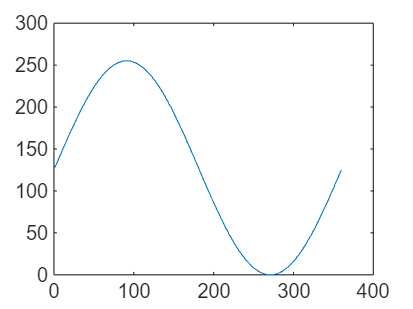

    elseif peakToPeak <= 127 && posOffset == 'n'

        sinCosTable.formatted = append(sinCosTable.formatted, sprintf('int8_t cosTable[%d] = {\r\n', nData));

// Auto generated sine LUT from SinCosLUTGenerator.m, credit: Alec Marshall 
uint8_t sinTable[360] = {
128,130,132,134,136,139,141,
143,145,147,150,152,154,156,158,
160,163,165,167,169,171,173,175,
177,179,181,183,185,187,189,191,
193,195,197,199,201,202,204,206,
208,209,211,213,214,216,218,219,
221,222,224,225,227,228,229,231,
232,233,234,236,237,238,239,240,
241,242,243,244,245,246,247,247,
248,249,249,250,251,251,252,252,
253,253,253,254,254,254,255,255,
255,255,255,255,255,255,255,255,
255,254,254,254,253,253,253,252,
252,251,251,250,249,249,248,247,
247,246,245,244,243,242,241,240,
239,238,237,236,234,233,232,231,
229,228,227,225,224,222,221,219,
218,216,214,213,211,209,208,206,
204,202,201,199,197,195,193,191,
189,187,185,183,181,179,177,175,
173,171,169,167,165,163,160,158,
156,154,152,150,147,145,143,141,
139,136,134,132,130,128,125,123,
121,119,116,114,112,110,108,105,
103,101,99,97,95,92,90,88,
86,84,82,80,78,76,74,72,
70,68,66,64,62,60,58,56,
54,53,51,49,47,46,44,42,
41,39,3

    elseif peakToPeak > 255 && posOffset == 'y'
        sinCosTable.formatted = append(sinCosTable.formatted, sprintf('uint16_t cosTable[%d] = {\r\n', nData));



 Output copied to clipboard 


    elseif peakToPeak > 127 && posOffset == 'n'
        sinCosTable.formatted = append(sinCosTable.formatted, sprintf('int16_t cosTable[%d] = {\r\n', nData));
    end
    for i = 1:nData
        if posOffset == 'y'
            sinCosTable.rawValues(1,i) = round((cos(stepSize*(i-1))+1)*peakToPeak/2,0);
        elseif posOffset == 'n'
            sinCosTable.rawValues(1,i) = round(cos(stepSize*(i-1))*peakToPeak/2,0);
        else
            fprintf('Not a valid offset selection \n')
            sinCosTable.rawValues = [];
            sinCosTable.formatted = 'Not a valid offset selection';
            return
        end
        if mod(i,8) == 0
            sinCosTable.formatted = append(sinCosTable.formatted, newline);
        end
        if format == 'd'
            sinCosTable.formatted = append(sinCosTable.formatted, sprintf('%d,',sinCosTable.rawValues(i)));
        elseif format == 'h'
            sinCosTable.formatted = append(sinCosTable.formatted, sprintf('0x%X,',sinCosTable.rawValues(i)));
        else
            fprintf("Not a valid format selection \n")
            sinCosTable.rawValues = [];
            sinCosTable.formatted = 'Not a valid format selection';
            return 
        end
    end
    sinCosTable.formatted = sinCosTable.formatted(1:end-1); % strip final comma
    sinCosTable.formatted = append(sinCosTable.formatted, '};');
else
    fprintf('Not a valid wave selection \n')
    sinCosTable.rawValues = [];
    sinCosTable.formatted = 'Not a valid wave selection';
    return
end
end

clc
posOffset = ' ';
waveType = ' ';
outFormat = ' ';
nData = 0;
pk2pk = 0;
while nData <= 0
    nData = input('Enter number of datapoints \n');
    if nData <= 0
        fprintf('Invalid number of datapoints \n')
    end
end 
period = input('Enter period (default = 2*pi) \n');
if isempty(period)
    period = 2*pi();
end
while pk2pk <= 0
    pk2pk = input('Enter peak-to-peak height \n');
    if pk2pk <= 0
        fprintf('Invalid peak to peak size \n')
    end
end
while not(posOffset == 'y') && not(posOffset == 'n')
    posOffset = input('Positive offset? (y/n) \n','s');
    if not(posOffset == 'y') && not(posOffset == 'n')
        fprintf('Invalid input, try again \n')
    end
end
while not(waveType == 'c') && not(waveType == 's')
    waveType = input('Wave type - Sine or Cosine? (c/s) \n','s');
    if not(waveType == 'c') && not(waveType == 's')
        fprintf('Invalid input, try again \n')
    end
end
if posOffset == 'y'
    while not(outFormat == 'h') && not(outFormat == 'd')
        outFormat = input('Output array format - Decimal or Hex (d/h) \n','s');
        if not(outFormat == 'h') && not(outFormat == 'd')
            fprintf('Invalid input, try again \n')
        end
    end
else
    fprintf('Hex format not possible without positive offset, defaulting to decimal')
    outFormat = 'd';
end

output = generateSinCosTable(nData, period, pk2pk, posOffset, waveType, outFormat);
plot(output.rawValues)
fprintf(output.formatted)
clipboard('copy', output.formatted);
fprintf('\n\n Output copied to clipboard \n');